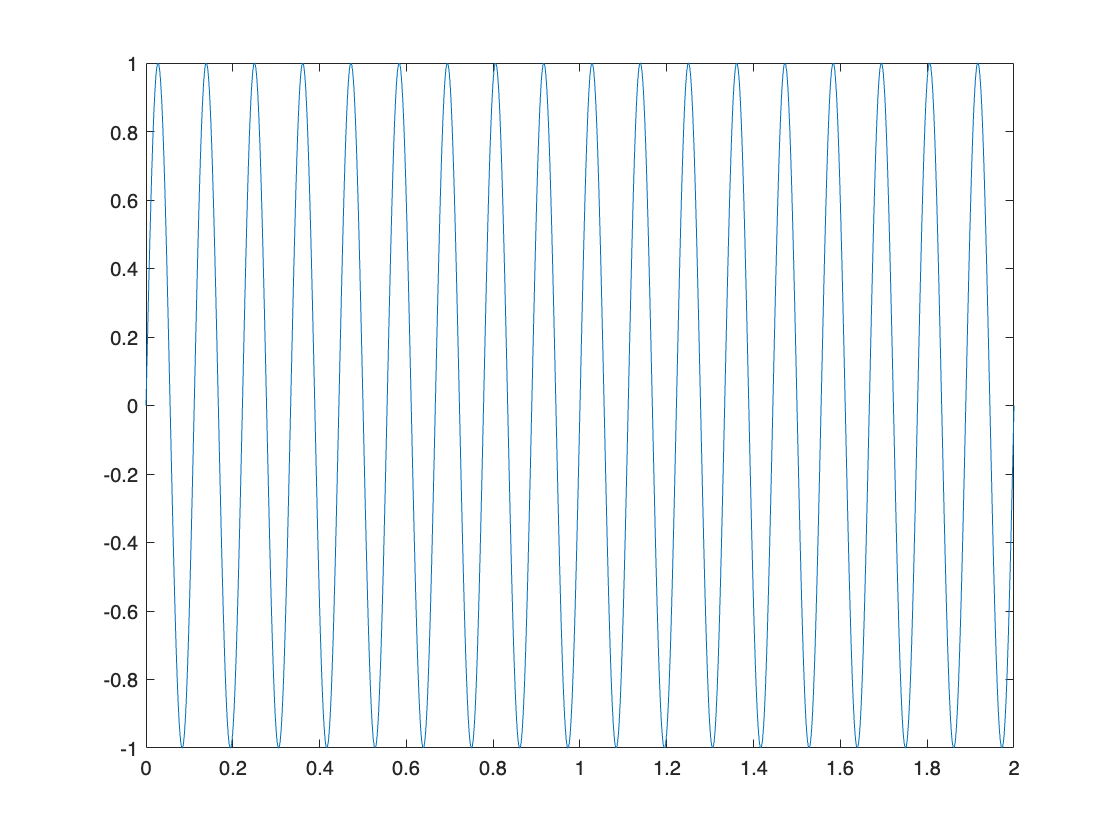

f_0 = 9;
f_dense = 1000;
T = 2;
t_0 = linspace(0,T,T*f_dense);
signal = sin(2*pi*f_0*t_0);
figure;
plot(t_0,signal);

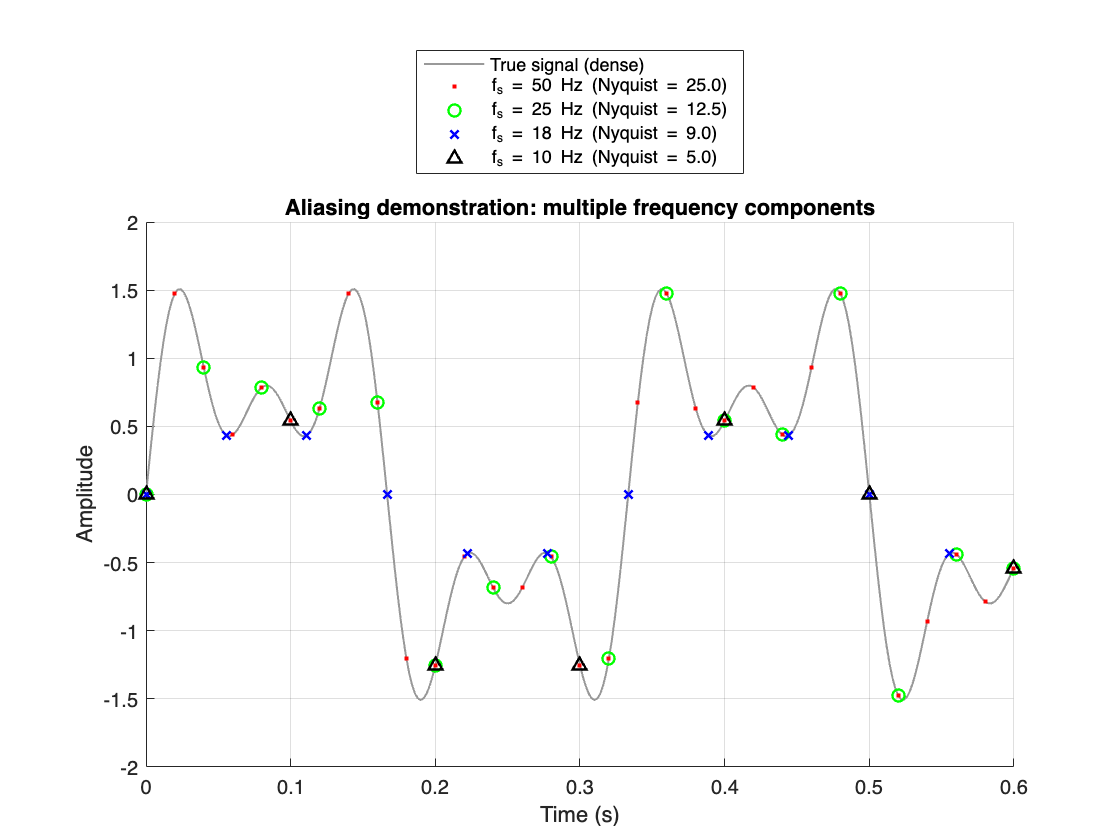

%% Multi-frequency aliasing demo
clear; close all;

% --- Dense “true” signal (acts like continuous time) ---
T       = 2;            % total duration [s]
f_dense = 500;          % dense sampling rate [Hz]
t_dense = 0:1/f_dense:T;

% True signal with 3, 9, and 15 Hz components
signal_dense = sin(2*pi*3*t_dense) ...
             + 0.7*sin(2*pi*9*t_dense) ...
             + 0.5*sin(2*pi*15*t_dense);

% --- Sampling rates to test ---
fs = [50, 25, 18, 10];           % Hz
markers = {'r.','go','bx','k^'}; % marker/color styles

figure; hold on;
plot(t_dense, signal_dense, 'Color', [0.6 0.6 0.6], 'LineWidth', 1);
legend_entries = {'True signal (dense)'};

% --- Sample and plot for each rate ---
for i = 1:length(fs)
    f_s = fs(i);
    t = 0:1/f_s:T;   % sample times
    x = sin(2*pi*3*t) ...
      + 0.7*sin(2*pi*9*t) ...
      + 0.5*sin(2*pi*15*t);
    plot(t, x, markers{i}, 'MarkerSize', 6, 'LineWidth', 1.2);
    legend_entries{end+1} = sprintf('f_s = %d Hz (Nyquist = %.1f)', f_s, f_s/2);
end

% --- Formatting ---
xlabel('Time (s)');
ylabel('Amplitude');
title('Aliasing demonstration: multiple frequency components');
legend(legend_entries, 'Location', 'northoutside');
xlim([0 0.6]);  % zoom in to see waveform differences
grid on;

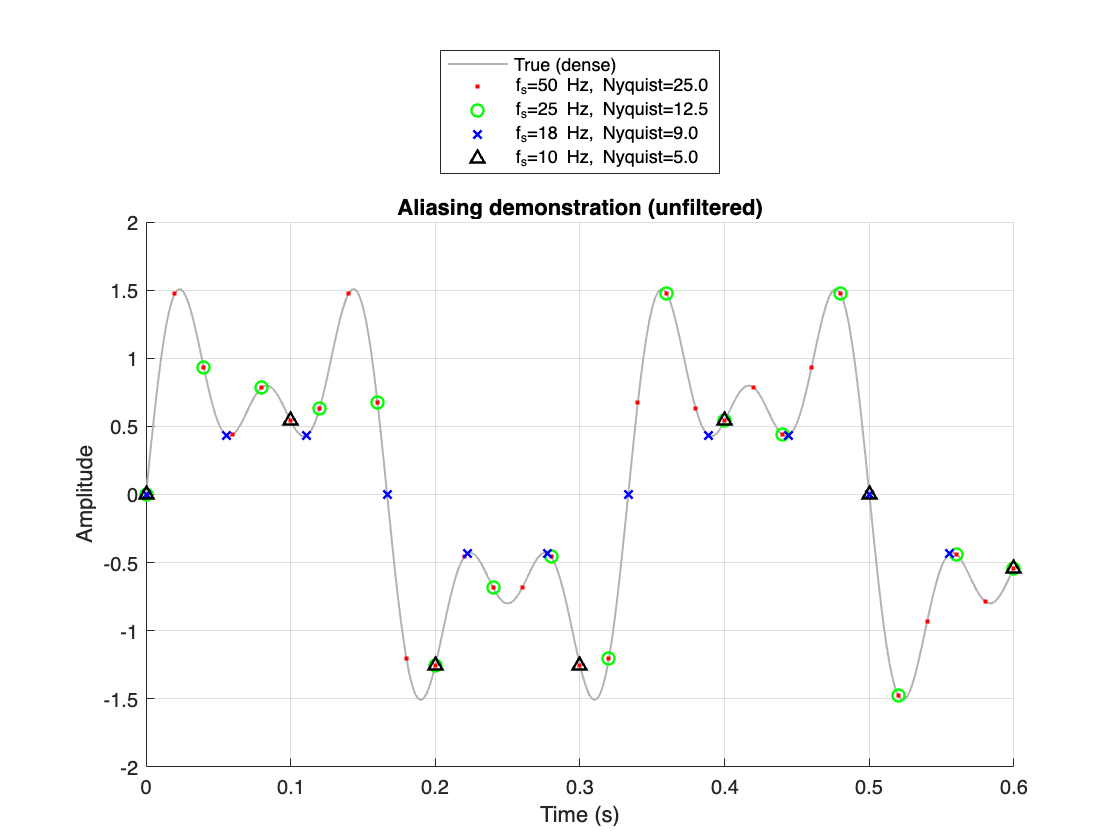

%% Aliasing and Anti-Aliasing Filter Demo
clear; close all;

% ---------- Original continuous-time-like signal ----------
T       = 2;            % seconds
f_dense = 500;          % dense sampling rate (acts continuous)
t_dense = 0:1/f_dense:T;

% 3 components: low, mid, and high frequencies
signal_dense = sin(2*pi*3*t_dense) ...
             + 0.7*sin(2*pi*9*t_dense) ...
             + 0.5*sin(2*pi*15*t_dense);

% ---------- Sampling rates ----------
fs_list = [50, 25, 18, 10];           % Hz
markers  = {'r.','go','bx','k^'};

% ---------- Plot dense reference ----------
figure('Name','Aliasing demo'); hold on;
plot(t_dense, signal_dense, 'Color',[0.7 0.7 0.7],'LineWidth',1);
legend_entries = {'True (dense)'};

% ---------- Unfiltered sampling ----------
for i = 1:length(fs_list)
    f_s = fs_list(i);
    t = 0:1/f_s:T;     % sample times
    x = sin(2*pi*3*t) ...
      + 0.7*sin(2*pi*9*t) ...
      + 0.5*sin(2*pi*15*t);
    plot(t, x, markers{i}, 'MarkerSize',6,'LineWidth',1.2);
    legend_entries{end+1} = sprintf('f_s=%d Hz, Nyquist=%.1f', f_s, f_s/2);
end

xlabel('Time (s)');
ylabel('Amplitude');
title('Aliasing demonstration (unfiltered)');
legend(legend_entries,'Location','northoutside');
xlim([0 0.6]); grid on;

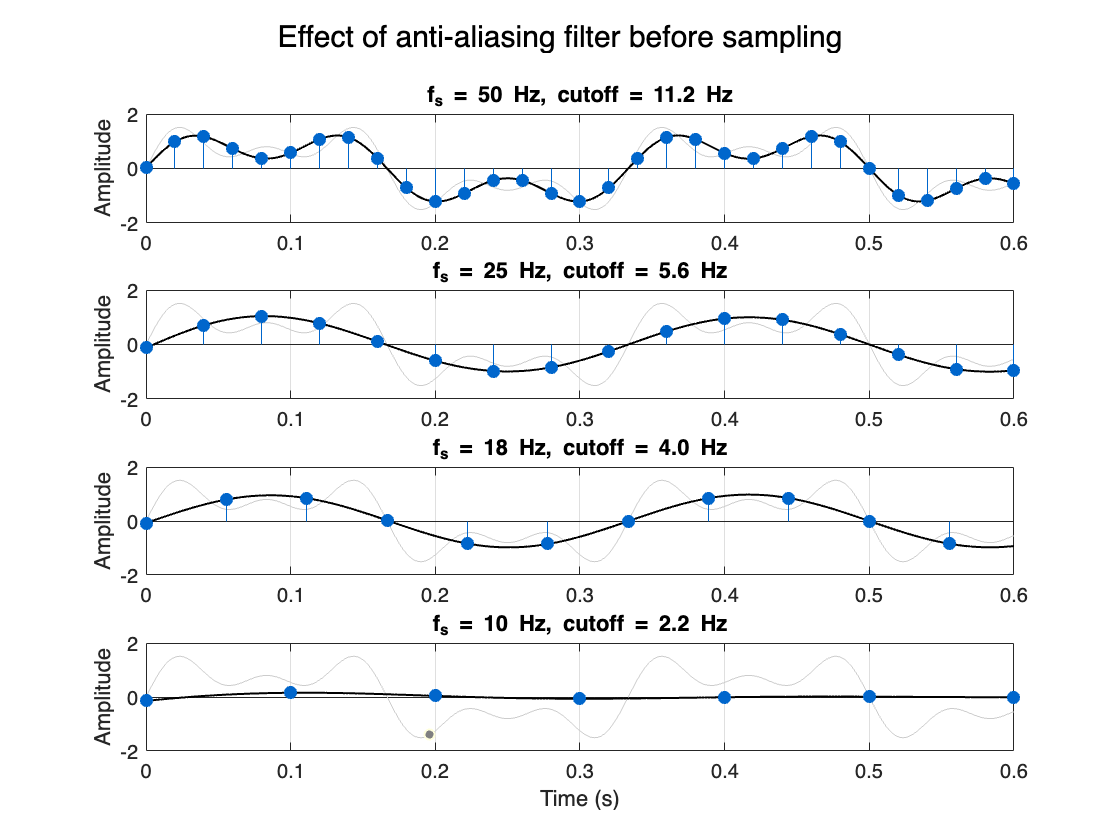



%% ---------- Apply an anti-aliasing filter ----------
% Design a low-pass filter with cutoff a bit below Nyquist (say 0.45*f_s)
figure('Name','With Anti-Aliasing Filter');

for i = 1:length(fs_list)
    f_s = fs_list(i);
    f_cut = 0.45 * (f_s/2);      % cutoff frequency
    [b,a] = butter(6, f_cut/(f_dense/2));  % 6th-order Butterworth, normalized by f_dense Nyquist
    filtered = filtfilt(b,a,signal_dense); % zero-phase filtering

    % Sample the filtered signal
    t = 0:1/f_s:T;
    x_filt = interp1(t_dense, filtered, t, 'linear');

    subplot(length(fs_list),1,i);
    plot(t_dense, signal_dense, 'Color',[0.8 0.8 0.8]); hold on;
    plot(t_dense, filtered, 'k','LineWidth',1);                 % filtered analog
    stem(t, x_filt, 'filled','Marker','o','Color',[0 0.4 0.8]); % sampled points
    title(sprintf('f_s = %d Hz, cutoff = %.1f Hz', f_s, f_cut));
    ylabel('Amplitude'); grid on;
    if i==length(fs_list), xlabel('Time (s)'); end
    xlim([0 0.6]);
end

sgtitle('Effect of anti-aliasing filter before sampling');

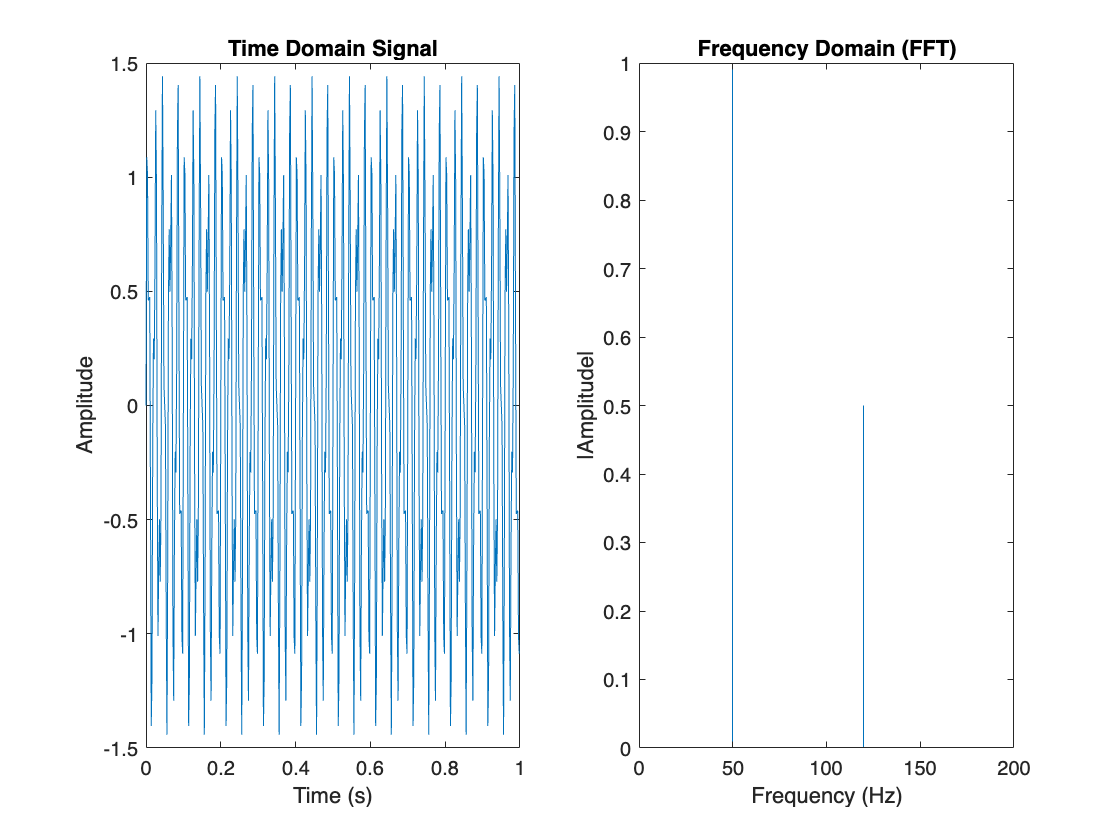

% --- 1. Create a signal ---
fs = 500;                     % Sampling frequency (Hz)
t = 0:1/fs:1-1/fs;            % Time vector (1 second)
f1 = 50; f2 = 120;            % Two frequencies (Hz)

% Combine two sinusoids
signal = sin(2*pi*f1*t) + 0.5*sin(2*pi*f2*t);

% --- 2. Compute FFT ---
N = length(signal);
Y = fft(signal);              % Compute FFT
f = (0:N-1)*(fs/N);           % Frequency axis

% --- 3. Keep only first half (positive frequencies) ---
half_N = floor(N/2);
f = f(1:half_N);
P2 = abs(Y/N);                % Two-sided spectrum
P1 = 2*P2(1:half_N);          % One-sided spectrum (amplitude correction)

% --- 4. Plot ---
figure;
subplot(1,2,1);
plot(t, signal);
title('Time Domain Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(1,2,2);
stem(f, P1, 'Marker', 'none');
title('Frequency Domain (FFT)');
xlabel('Frequency (Hz)');
ylabel('|Amplitude|');
xlim([0 200]);